# BERTによる埋め込み表現の取得とその比較

BERTは、単語の埋め込み表現に文脈を加味する。それを確かめるために、以下のスクリプトを動作させる。

clear;
mdl = bert;
tokenizer = mdl.Tokenizer

tokenizer =   BERTTokenizer のプロパティ:

      PaddingToken: "[PAD]"
        StartToken: "[CLS]"
    SeparatorToken: "[SEP]"
         MaskToken: "[MASK]"
     FullTokenizer: [1×1 bert.tokenizer.internal.FullTokenizer]
       PaddingCode: 1
     SeparatorCode: 103
         StartCode: 102
          MaskCode: 104


同じ"take"を使っているが、前後の語順(=context)が異なる文章を用意する。

str1 = "I'll take this hat."; idx1 = 5;
str2 = "I'll take his hat."; idx2 = 5;
str3 = "You'll take this hat."; idx3 = 5;

各文字列に対してトークン化(単語の最小単位に分割)を行う。トークン化された文字列をtable1として表示する。比較のため、今回はトークン長と"take"の位置が同じ文章を用意した。いずれの文も、トークン長は9、"take"の位置はトークンの5番目にある。

tokens1 = tokenize(tokenizer, str1);
tokens2 = tokenize(tokenizer, str2);
tokens3 = tokenize(tokenizer, str3);
tbl1 = table;
tbl1.tokens1 = tokens1{1}';
tbl1.tokens2 = tokens2{1}';
tbl1.tokens3 = tokens3{1}'

tbl1 = 9×3 table
    tokens1    tokens2    tokens3
    _______    _______    _______

    "[CLS]"    "[CLS]"    "[CLS]"
    "i"        "i"        "you"  
    "'"        "'"        "'"    
    "ll"       "ll"       "ll"   
    "take"     "take"     "take" 
    "this"     "his"      "this" 
    "hat"      "hat"      "hat"  
    "."        "."        "."    
    "[SEP]"    "[SEP]"    "[SEP]"


トークン化された文字列をエンコードする。エンコードすると内部表現になるため、人の目では元の文章は分からない。エンコードは単語を常にある1つの表現に変換するだけなので、この時点では文脈の加味はできていない。エンコード結果はtable2に示す。

X1 = encodeTokens(tokenizer, tokens1);
X2 = encodeTokens(tokenizer, tokens2);
X3 = encodeTokens(tokenizer, tokens3);
tbl2 = table;
tbl2.X1 = X1{1}';
tbl2.X2 = X2{1}';
tbl2.X3 = X3{1}'

tbl2 = 9×3 table
     X1      X2      X3 
    ____    ____    ____

     102     102     102
    1046    1046    2018
    1006    1006    1006
    2223    2223    2223
    2203    2203    2203
    2024    2011    2024
    6046    6046    6046
    1013    1013    1013
     103     103     103


実際に埋め込み表現を計算してみる。ハイパーパラメーターは読み込んだBERTモデルに依存する。得られる埋め込み表現は、768×トークン長の大きな行列になっているため、今回比較する"take"の埋め込み表現だけ取り出す。隠れ層の大きさが768次元なので、1単語に対応する埋め込み表現(ベクトル)は768次元になる。

Z1 = bert.model(X1{1}, mdl.Parameters);
Z2 = bert.model(X2{1}, mdl.Parameters);
Z3 = bert.model(X3{1}, mdl.Parameters);
embedded_rep1 = Z1(:, idx1);
embedded_rep2 = Z2(:, idx2);
embedded_rep3 = Z3(:, idx3);
tbl3 = table;
vecsize = mdl.Parameters.Hyperparameters.HiddenSize;
dst = zeros(vecsize, 1);
for i = 1:vecsize
    dst(i, 1) = embedded_rep1(i);
end
tbl3.emb1 = dst;
for i = 1:vecsize
    dst(i, 1) = embedded_rep2(i);
end
tbl3.emb2 = dst;
for i = 1:vecsize
    dst(i, 1) = embedded_rep3(i);
end
tbl3.emb3 = dst

tbl3 = 768×3 table
       emb1         emb2        emb3   
    __________    ________    _________

      -0.11605     0.14198     -0.23007
      -0.54692     -0.1859     -0.84125
       0.71545     0.62497      0.58786
    -0.0024345     -0.1845    -0.048128
       0.24408     0.31946       0.3978
      -0.67971    -0.70007     -0.57317
      -0.26732    -0.49866      0.14858
       0.13083    -0.36921      0.57346
       0.48266     0.57196      0.23686
      0.091848    0.070762    -0.018447
       0.54624      0.2886      0.33726
       0.14031    0.083318      0.26594
      -0.42327    -0.51584      -0.4411
      -0.55329    -0.56616     -0.48371
      -0.47522    -0.46936        -0.49
       0.69263     0.54537      0.45925


同じ単語に対して、文脈によって異なる埋め込み表現が得られたのか確かめるために、散布図にしてみる。そのためにも、まずは得られた埋め込み表現を簡単に扱うことができるデータ型に変換する。今回は得られた埋め込み表現を、全て2次元配列に格納し直す。

len = length(tokens1{1});
mat1 = zeros(vecsize, len);
for i = 1:vecsize
    for j = 1:len
        mat1(i, j) = Z1(i, j);
    end
end
len = length(tokens2{1});
mat2 = zeros(vecsize, len);
for i = 1:vecsize
    for j = 1:len
        mat2(i, j) = Z2(i, j);
    end
end
len = length(tokens3{1});
mat3 = zeros(vecsize, len);
for i = 1:vecsize
    for j = 1:len
        mat3(i, j) = Z3(i, j);
    end
end

そこから、もう一度"take"の単語に相当する部分のみをveci (i=1～3)に格納する。実際に散布図にして比較した画像を出力する。もし、比較しているベクトル同士が全く同じであれば、散布図は右下のプロットのように一直線になるはずだが、いずれの比較散布図も、その通りではない。つまり、文脈によって異なる埋め込み表現を得ることができた。

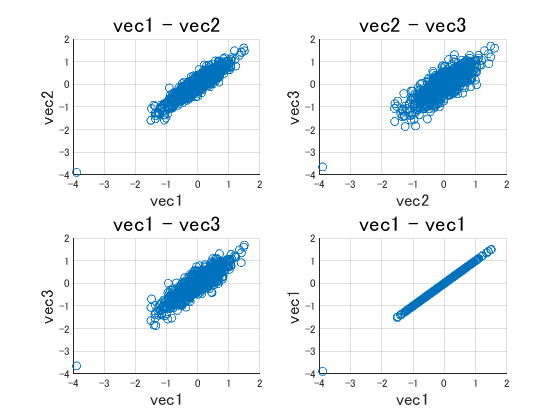

vec1 = mat1(:, idx1);
vec2 = mat2(:, idx2);
vec3 = mat3(:, idx3);

subplot(2, 2, 1);
scatter(vec1, vec2);
title("vec1 - vec2", "FontSize", 16);
xlabel("vec1", "FontSize", 13);
ylabel("vec2", "FontSize", 13);
grid on;

subplot(2, 2, 2);
scatter(vec2, vec3);
title("vec2 - vec3", "FontSize", 16);
xlabel("vec2", "FontSize", 13);
ylabel("vec3", "FontSize", 13);
grid on;

subplot(2, 2, 3);
scatter(vec1, vec3);
title("vec1 - vec3", "FontSize", 16);
xlabel("vec1", "FontSize", 13);
ylabel("vec3", "FontSize", 13);
grid on;

subplot(2, 2, 4);
scatter(vec1, vec1);
title("vec1 - vec1", "FontSize", 16);
xlabel("vec1", "FontSize", 13);
ylabel("vec1", "FontSize", 13);
grid on;

figure;